# The SI Model

#### **The Model**

The SI model is the simplest form of all compartmental disease models. Individuals are born into the simulation with no immunity, therefore they are susceptible.The dynamics of the infected in a SI model are also known as logistic growth, once infected and with no treatment, individuals stay infected and infectious throughout their life, and remain in contact with the susceptible population. This model matches the behavior of diseases like herpes.

This model for the spread of a disease is dependant upon the state variables S and I.

The image below shows what the block diagram for the SI model looks like.

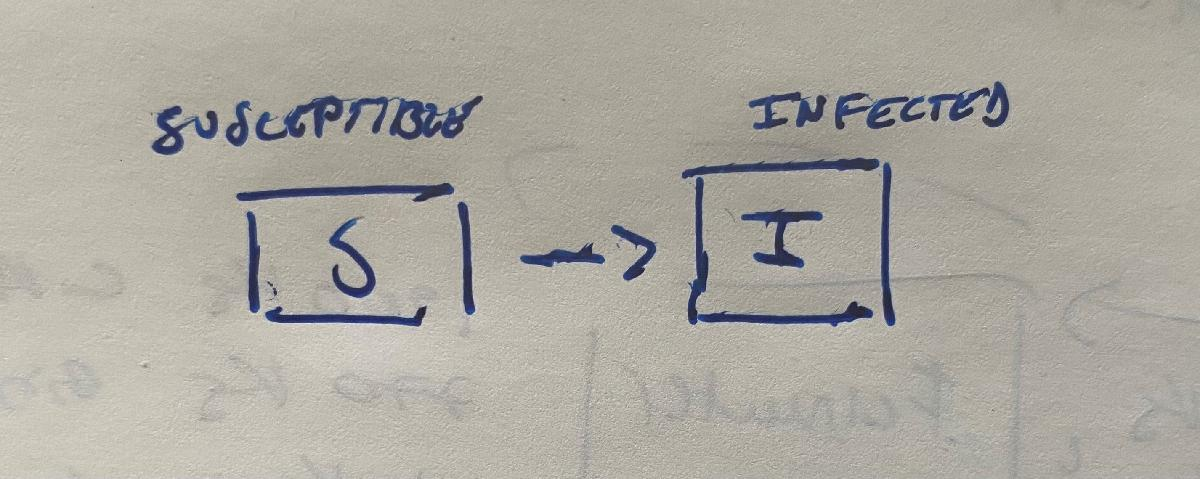

The differential equations of the SI model are:


$$$$\frac{dS}{dt}=- \beta I S$$



$$$$\frac{dI}{dt}=\beta IS$$


where $N=S+I$ is the total population

The parameters are:

- $\beta$ is referred to as the infection rate and is defined as the product between the infection probability $p$ and the contact rate $c$, divided by the total population. In fact, its value depends on the transmissability of the disease, which is accounted for with $p$, and the frequency that members of a population gather for social reasons, which is expressed as $c$.

**Mathematical analysis for SI model (exact solution)**

The SI model can be written as the following ODEs:


$$S' (t)= - \beta SI$$



$$I'(t)=\beta SI$$


The initial conditions are


$$I(0)={I}_0  $$
      
$$S(0)={S}_0  $$


; where $\beta > 0  $, ${I}_0 > 0$ and ${S}_0 > 0$. ($\beta$ is the infectivity coefficient)

It can be acknowledged that $S(t) +I(t)= N$, where $N$ is the number of the total population.

By using $S(t)= N-I(t)$ in the $dI$equation, we get:


$$I'=\beta (N-I)I$$


Integrating the equation above with the substitution $y=I^-$ leads to


$${y\;e}^{\left(\beta N\right)t} =\int \beta {\;e}^{\left(\beta N\right)t} \;\textrm{dt}+C$$
 

After solving the equation and changing $\beta N=r$, it is obtained:


$$y=\frac{\beta +r\;C\;e^{-\textrm{rt}} }{r}$$


By using again the substitution $y=I^-$, we get


$$I\left(t\right)=\frac{r}{\beta +r\;C\;e^{-\textrm{rt}} }$$


We can then apply the initial condition $I(0)={I}_0$, transforming the previous equation into,


$$C=\frac{r-I_0 \beta }{r\;I_0 }$$


Finally resulting in the exact solution for $I$

$I\left(t\right)=\frac{r}{\beta +r\left(\frac{r-I_0 \beta }{rI_0 }\right)\;e^{-r\;t} }$ or


$$I\left(t\right)=\frac{\;I\left(0\right)N}{I\left(0\right)+\exp \left(-\beta t\right)\left(N-I\left(0\right)\right)}$$


The exact solution for $S$ can be obtained by replacing the  new $I\left(t\right)$in the $S(t) +I(t)= N$ equation.

## Solution with Euler method

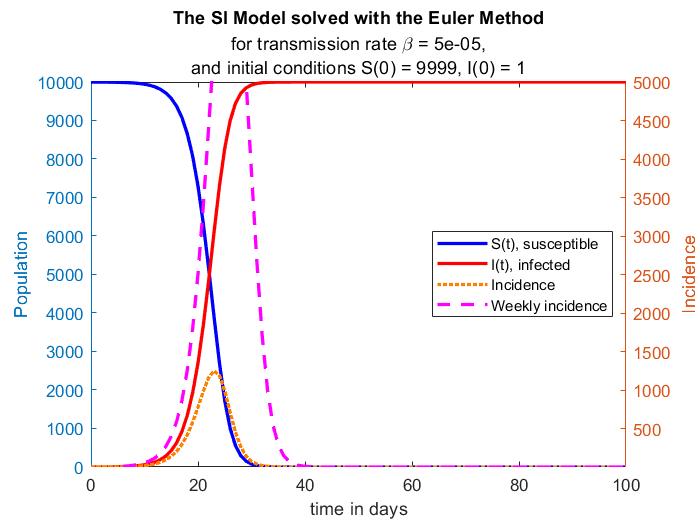

figure;

%%% The initial values

tmax = 100;

S = zeros(1, tmax + 1);
I = zeros(1, tmax + 1);

S(1) = 9999;
I(1) = 1;
N=S(1)+I(1);

Incidence = zeros(1, tmax + 1);
Incidence(1) = 0;

Weekly_Incidence = zeros(1, tmax - 6);

%%% The parameters

p=0.1;  % infection probability 
c=5;    % contact rate

beta = p*c/N;


%%% The Euler method

T = zeros(1,tmax + 1);
T(1) = 0;

for t = 1:tmax
        
    T(t+1) = t;
    
    S(t+1) = S(t) - beta*I(t)*S(t);   
    I(t+1) = I(t) + (beta*I(t)*S(t));    
    
    Incidence(t+1) = beta*I(t)*S(t);
    
        if t > 5
                
            Weekly_Incidence(t-5) = sum(Incidence(t-5:t+1));
            
        end
end


%%%% The plot

yyaxis left
plot(T, S, 'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(T, I, 'r','LineWidth',2,'LineStyle',"-");
ylabel('Population');

yyaxis right 
plot(T, Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(T(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylim([1 5000]);
ylabel('Incidence');

title('The SI Model solved with the Euler Method')
subtitle({['for transmission rate \beta = ',num2str(beta),','], ...
    ['and initial conditions S(0) = ',num2str(S(1)),', I(0) = ',num2str(I(1))]})
legend('S(t), susceptible', 'I(t), infected','Incidence', 'Weekly incidence', 'Location', 'east')

xlabel('time in days');
xlim([0 100]);

hold off;

## Solution with ode45

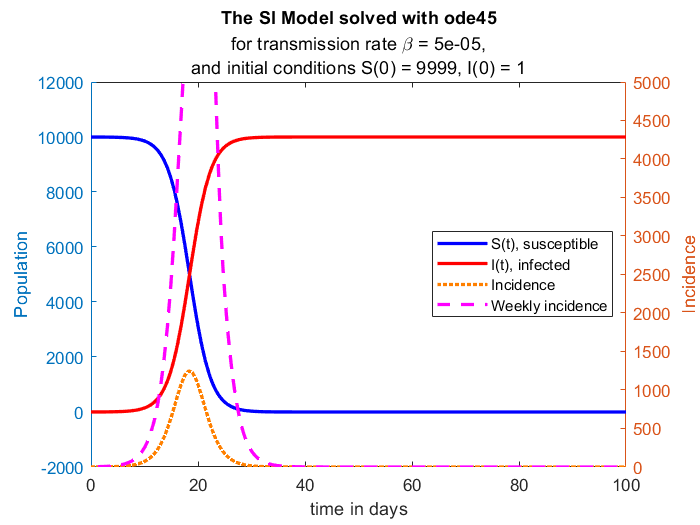

figure;

%%%% The parameters and the initial values

tRange = [0 100];
beta = 0.00005;
Y0 = [9999; 1];

[tSol,YSol] = ode45(@SImodel,tRange,Y0);

%%%% The plot

S = YSol(:,1);
I = YSol(:,2);

Incidence = beta*S.*I;

sz = size(tSol);
Weekly_Incidence = zeros(sz(1)-6,sz(2));

for n = 7:sz(1)

    Weekly_Incidence(n-6) = sum(Incidence(n-6:n));
 
end

yyaxis left
plot(tSol,S,'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(tSol,I,'r','LineWidth',2,'LineStyle',"-");
ylabel('Population');

yyaxis right
plot(tSol,Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(tSol(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylabel('Incidence');
ylim([0 5000]);

legend('S(t), susceptible', 'I(t), infected','Incidence', 'Weekly incidence', 'Location', 'east');
title('The SI Model solved with ode45');
subtitle({['for transmission rate \beta = ',num2str(beta),','], ...
    ['and initial conditions S(0) = ',num2str(Y0(1)),', I(0) = ',num2str(Y0(2))]})

xlabel('time in days');
xlim([0 100]);
hold off;

## Phase Diagram for the SI model

A **phase portrait** or **phase diagram** illustrates the behavioural trend that a dynamical system undergoes as time goes by. In the case of an SI model, a phase diagram depicts the number of infected individuals $I$ against the number of susceptible $S$. The resulting curve shows how the numbers of susceptible and infected cases interactively vary as the epidemics develops, starting from the bottom right corner, up along the curve and down to the bottom left corner of the graph.

Finally, the steepness of the curve hints for how fast the disease is spreading or diying off at that given point in terms of $S$ and $I$.

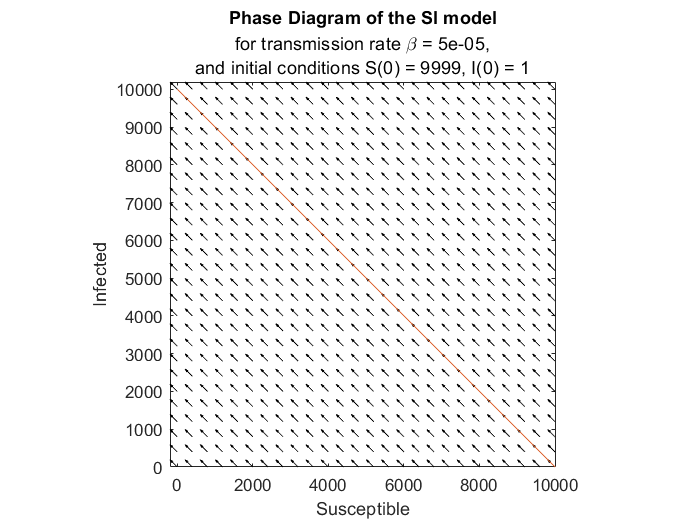

figure

%%vector field
[S,I]=meshgrid(0:400:10000,0:400:10000);
U=-beta*S*I;
V=beta*S*I;
L=sqrt(U.^2+V.^2);
quiver(S,I,U./L,V./L,0.5,'k')
axis equal tight

%%%% The solution on the plot

hold on
tRange = [0 100];
beta = 0.00005;
Y0 = [9999; 1];

[tSol,YSol] = ode45(@SImodel,tRange,Y0);

S = YSol(:,1);
I = YSol(:,2);
plot(S,I)
xlabel('Susceptible')
ylabel('Infected')
title('Phase Diagram of the SI model')
subtitle({['for transmission rate \beta = ',num2str(beta),','], ... 
    ['and initial conditions S(0) = ',num2str(Y0(1)),', I(0) = ',num2str(Y0(2))]})

hold off

function dYdt = SImodel(~,Y)  

    % Extract S and I from input vector Y
    S = Y(1); % susceptible
    I = Y(2); % infected
    
    % Define the constant beta
    beta = 0.00005;
    
    % Define dSdt and dIdt from the ODEs
    dSdt = -beta*S*I;
    dIdt = beta*S*I ;
    
    % Create output column vector dYdt
    dYdt = [dSdt; dIdt];
    
end
